## 🚀 Initialization

clc; clear all;

% Parent directory
par_dir = pwd;

% Add path to subfunction
addpath(strcat(par_dir,'/matlab_subfunc'));

% Specify the data folder path
data_folder = 'data/';

% Get a list of all files in the data folder
files = dir(fullfile(data_folder, '*.csv'));

## 🧹 Preprocess

% Initialize an empty array of structs
fileData = struct('fileName', {}, ...
                  'error', {}, ...
                  'acc_error', {}, ...
                  'inlet_water_temp', {}, ...
                  'return_air_temp', {}, ...
                  'return_air_rh', {}, ...
                  'wshp_power', {}, ...
                  'sen_load', {}, ...
                  'lat_load', {}, ...
                  'air_cfm', {});

% Loop through the file paths
for i = 1:length(files)
    file = files(i).name;
    fprintf('i: %d, file: %s\n', i, file);

    % Get the file path of the selected file
    file_path = fullfile(data_folder, file);

    % Read the csv file
    data = readtable(file_path,"PreserveVariableNames",true);
    
    % Remove rows where 'Simulation Time Step' is <= 0 and >=1339
    data = data(data.('Simulation Time Step') > 0 & data.('Simulation Time Step') < 1339, :);
    
    % Extract columns based on their names or patterns
    simulation_time_step = data.('Simulation Time Step');
    sim_zone_temp = data{:, contains(data.Properties.VariableNames, 'Sim Zone Temp')};
    active_setpoint = data{:, contains(data.Properties.VariableNames, 'Active Setpoint')};
    inlet_water_temp = data{:, contains(data.Properties.VariableNames, 'Inlet Water Temp')};
    return_air_temp = data{:, contains(data.Properties.VariableNames, 'WSHP Return Air Temp')};
    return_air_rh = data{:, contains(data.Properties.VariableNames, 'WSHP Return Air RH')};
    wshp_power = data{:, contains(data.Properties.VariableNames, 'WSHP Power')}/1000;   % convert to kW
    sen_load = data{:, contains(data.Properties.VariableNames, 'Meas Sensible Load')};
    lat_load = data{:, contains(data.Properties.VariableNames, 'Meas Latent Load')};
    air_cfm = data{:, contains(data.Properties.VariableNames, 'WSHP Air Flowrate')};
    
    % Calculate error
    error = sim_zone_temp - active_setpoint;

    % Smooth the data

    
    % Calculate accumulated error
    criteria_series = wshp_power;
    reset_threshold = 0.15;
    acc_error = accumulated_errors(sim_zone_temp, active_setpoint, criteria_series, reset_threshold);
    
    % Smooth the data (continue)
    min_avg = 15;
    windowSize = min_avg * 12;    
    error_avg = movmean(error, windowSize);
    acc_error_avg = movmean(acc_error, windowSize);
    inlet_water_temp_avg = movmean(inlet_water_temp, windowSize);
    return_air_temp_avg = movmean(return_air_temp, windowSize);
    return_air_rh_avg = movmean(return_air_rh, windowSize);
    wshp_power_avg = movmean(wshp_power, windowSize);
    sen_load_avg = movmean(sen_load, windowSize);
    lat_load_avg = movmean(lat_load, windowSize);
    air_cfm_avg = movmean(air_cfm, windowSize);  
    
    % Store the data
    fileData(i).fileName = file;
    fileData(i).error = error_avg; 
    fileData(i).acc_error = acc_error_avg; 
    fileData(i).inlet_water_temp = inlet_water_temp_avg; 
    fileData(i).return_air_temp = return_air_temp_avg; 
    fileData(i).return_air_rh = return_air_rh_avg; 
    fileData(i).wshp_power = wshp_power_avg; 
    fileData(i).sen_load = sen_load_avg; 
    fileData(i).lat_load = lat_load_avg; 
    fileData(i).air_cfm = air_cfm_avg; 
end

i: 1, file: Test_AtlantaSHiftExtSum_07162023_0005.csv
i: 2, file: Test_AtlantaShiftDefault_061623_1055.csv
i: 3, file: Test_AtlantaShiftSTD2019_04092023_2320.csv
i: 4, file: Test_AtlantaTES_04222023_2302.csv
i: 5, file: Test_Atlanta_Default_1hr_110123_1357.csv
i: 6, file: Test_Atlanta_Default_MPC_Pretest_122723_1025.csv
i: 7, file: Test_Atlanta_Default_Random_102923_1331.csv
i: 8, file: Test_Atlanta_Default_random2_102623_2106.csv
i: 9, file: Test_Atlanta_Default_random_102423_1727.csv
i: 10, file: Test_BuffaloShiftDef_06022023_1805.csv
i: 11, file: Test_BuffaloShiftDenseOcc_06142023_2109.csv
i: 12, file: Test_BuffaloShiftExtSum_060323_2005.csv
i: 13, file: Test_BuffaloShiftSTD2019_060723_1026.csv
i: 14, file: Test_BuffaloShiftSaveBehave_06182023_0242.csv
i: 15, file: Test_NewYorkShiftDef_03312023_1837.csv
i: 16, file: Test_NewYorkShiftDenseOcc_04012023_2115.csv
i: 17, file: Test_NewYorkShiftSTD2019_05312023_2327.csv
i: 18, file: Test_TucsonShiftDef_032523_1125.csv
i: 19, file: Test_Tu

## 🏗️ Virtual testbed development

### 🧩 Prepare data

% % Number of files in fileData
% numFiles = length(fileData);
% 
% % Random exclude
% numExcludes = 4;
% excludeIndices = randperm(numFiles, numExcludes);
% 
% % Select data
% selectIndex = ~ismember(1:numFiles, excludeIndices);
% selectData = fileData(selectIndex);
selectData = fileData;

% Initialize feature and targets
x1 = [];
x2 = [];
x3 = [];
x4 = [];
x5 = [];
y1 = [];
y2 = [];
y3 = [];
y4 = [];

% Combine data from selectData
for i = 1:length(selectData)
    x1 = [x1;selectData(i).error];
    x2 = [x2;selectData(i).acc_error];
    x3 = [x3;selectData(i).inlet_water_temp];
    x4 = [x4;selectData(i).return_air_temp];
    x5 = [x5;selectData(i).return_air_rh];
    y1 = [y1;selectData(i).wshp_power];
    y2 = [y2;selectData(i).sen_load];
    y3 = [y3;selectData(i).lat_load];
    y4 = [y4;selectData(i).air_cfm];
end

### 🤖 Power model development

#### 📥 Feature space

% Form feature space
X = [x1,x2,x3,x4,x5];

#### 🔁 Cross validation

% % Assume X and y1 are already defined
% nFolds = 10;
% cv = cvpartition(size(X, 1), 'KFold', nFolds);
% 
% rmseVals = zeros(nFolds, 1); % Preallocate array for RMSE values
% 
% % Enable parallel computing
% if isempty(gcp('nocreate')) % If no parallel pool, create a new one
%     parpool;
% end
% 
% % Parallel for loop for cross-validation
% parfor i = 1:nFolds
%     trainIdx = cv.training(i);
%     testIdx = cv.test(i);
%     
%     % Train the model
%     power_model = TreeBagger(50, X(trainIdx,:), y1(trainIdx), 'Method', 'regression');
%     
%     % Predict on validation set
%     predictions = predict(power_model, X(testIdx,:));
%     
%     % Calculate RMSE for this fold
%     rmseVals(i) = sqrt(mean((predictions - y1(testIdx)).^2));
% end
% 
% % Compute average RMSE
% averageRMSE = mean(rmseVals);
% 
% % Display results
% disp('RMSE for each fold:');
% disp(rmseVals);
% disp(['Average RMSE across all folds: ', num2str(averageRMSE)]);

#### 🏋️‍♂️ Train

% Train model using selectData
power_model = TreeBagger(50, X, y1, 'Method', 'regression', "OOBPrediction", "on", "OOBPredictorImportance", "on");

% % Accessing the feature importance
% featureImportance = power_model.OOBPermutedVarDeltaError;
% 
% % Displaying the feature importance
% figure;
% bar(featureImportance);
% xlabel('Feature Number');
% ylabel('Importance');
% title('Feature Importance');

% Save the model
save('wshp_power_model.mat','power_model')

#### ✍️ Manual validation

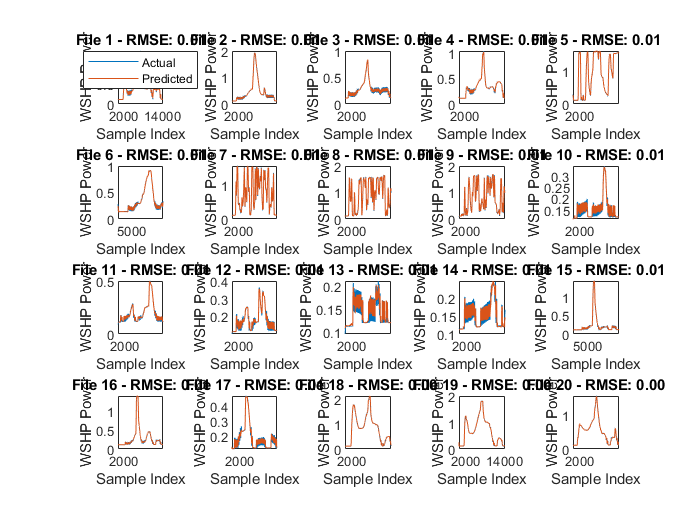

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error,...
             fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_rh];
   
    % Actual target value
    y1_act = fileData(i).wshp_power;
    
    % Predicted target value
    y1_pred = predict(power_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((y1_act - y1_pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(y1_act); % Actual in blue
    hold on;
    plot(y1_pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('WSHP Power');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(y1_act)]);
    
end

### 🤖 Sensible load model development

#### 📥 Feature space

% Form feature space
X = [x1,x2,x3,x4,x5];

#### 🏋️‍♂️ Train

% Train model using selectData
power_model = TreeBagger(50, X, y2, 'Method', 'regression');

#### ️ ✍️ Manual validation

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData)
    % Features
    X_val = [fileData(i).error,...
             fileData(i).acc_error,...
             fileData(i).inlet_water_temp,...
             fileData(i).return_air_temp,...
             fileData(i).return_air_rh];
   
    % Actual target value
    y1_act = fileData(i).wshp_power;
    
    % Predicted target value
    y1_pred = predict(power_model, X_val);

    % Calculate RMSE
    rmse = sqrt(mean((y1_act - y1_pred).^2));
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(y1_act); % Actual in blue
    hold on;
    plot(y1_pred); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Sample Index');
    ylabel('Sen Load');
    if i == 1
        legend({'Actual', 'Predicted'}, 'Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(y1_act)]);
    
end